# Membrane Optimizer

% Initial value of stage cut
initial = [5,15];
lowerbound = [5,5];
upperbound = [1000,60];

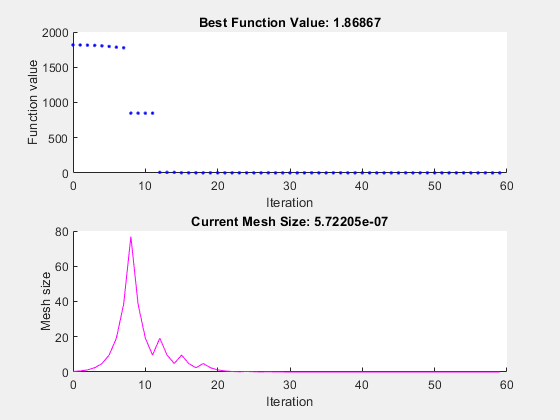

% Set nondefault solver options
options2 = optimoptions('patternsearch','InitialMeshSize',0.3,'Display','off',...
    'PlotFcn',{'psplotbestf','psplotmeshsize'});

% Solve
[solution,objectiveValue] = patternsearch(@objfunc_s0e0,initial,[],[],[],[],...
    lowerbound,upperbound,[],options2);


% Clear variables
clearvars options2

## List of stage cut parameters

y = choose(solution,'s1e1')

y =    -0.3713    5.0000    5.0000


function y = choose(X,names)
    xF = 0.25;
    yP = 0.9;
    xR = 0.03;
    theta_ov = (xF - xR)/(yP - xR);
    switch names
        case 's1e0' 
            theta_F = 1/(((1/theta_ov -1)*(1/(1-X)))+1);
        case {'s0e1'}
            theta_F = 1/(1+(1/theta_ov - 1)*X);
        case {'s0e2'}
            theta_F = 1 / (1 + (1/theta_ov - 1)*X(1)*X(2));
        case {'s1e1'}
            theta_F = 1 / (1 + (1/theta_ov - 1)*X(2)/(1-X(1)));
        otherwise
            warning('Unexpected structure')
    end
    y = [theta_F,X];
end